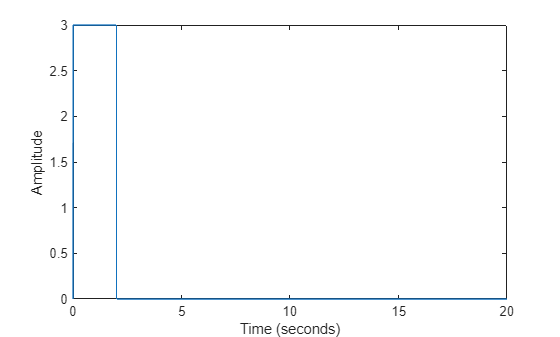

clc;
fs = 100;
dt = 1/fs;
total_time = 20;
N = fs*total_time;
M = fs*2;
t = (0:(N-1))*dt;
x = zeros(1,N);
x(t>0 & t<=2) = 3;
plot (t,x)
ylabel ('Amplitude');
xlabel ('Time (seconds)');

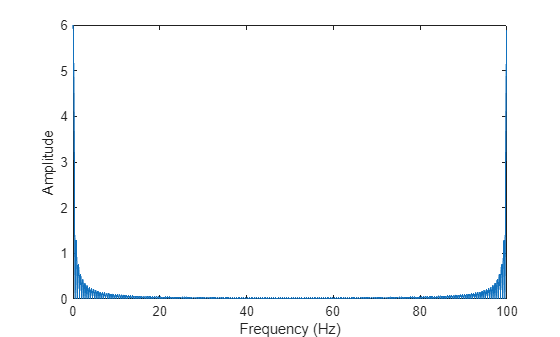

k = N;
X = fft(x)*dt;
X = abs(X);
y = fft(x);
y = abs(y);
y = y/fs;
f = (0:length(y)-1)*fs/length(y);
df = fs/N;
f = (0:N-1)*df;
plot(f, y)
ylabel('Amplitude');
xlabel('Frequency (Hz)');

EN_time = trapz(t,(x.^2))

EN_time = 18

EN_frequency = sum(y.^2) * df

EN_frequency = 18